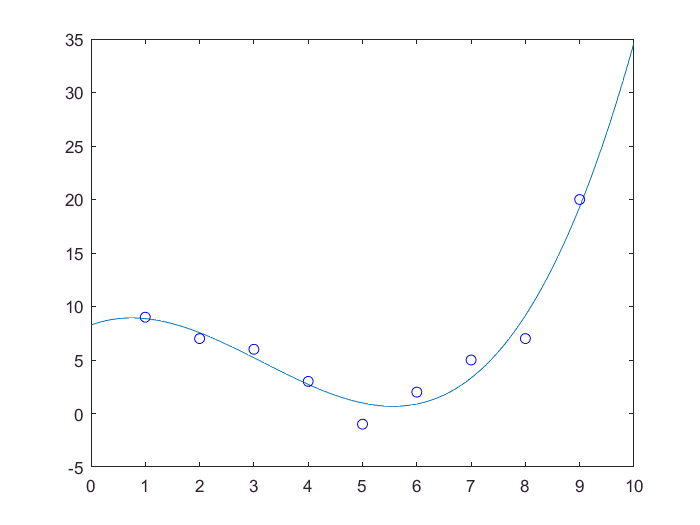

x = [1 2 3 4 5 6 7 8 9];
y = [9 7 6 3 -1 2 5 7 20];
P = polyfit(x,y,3);
xi = 0:.1:10;
yi = polyval(P,xi);
plot(xi,yi,x,y,'bo');

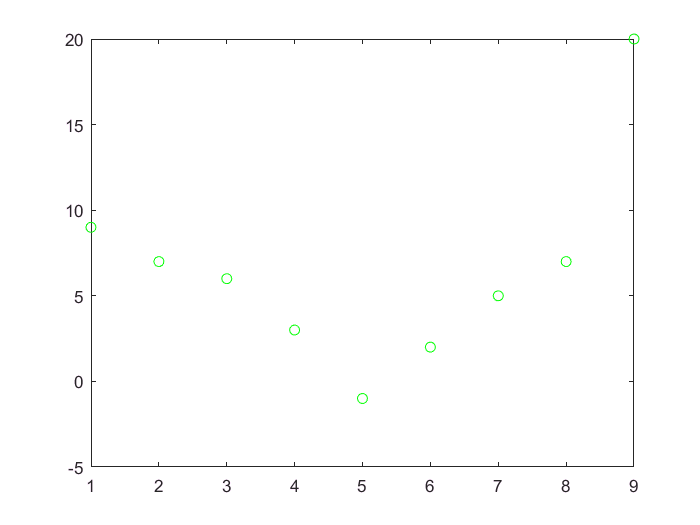


plot(x,y,'go');


x = [0;0.4;1.2;2;2.8;3.6;4.4;5.2;6;7.2;8;9.2;10.4;11.6;12.4;13.6;14.4;15];
y = [1;0.85;0.29;-0.27;-0.53;-0.4;-0.12;0.17;0.28;0.15;-0.03;-0.15;-0.071;0.059;0.08;0.032;-0.015;-0.02];

f = fittype('a*cos(k*t)*exp(w*t)','independent','t','coefficients',{'a','k','w'})

f =      General model:
     f(a,k,w,t) = a*cos(k*t)*exp(w*t)

cfun = fit(x,y,f)

cfun =      General model:
     cfun(t) = a*cos(k*t)*exp(w*t)
     Coefficients (with 95% confidence bounds):
       a =           1  (0.9742, 1.027)
       k =       14.71  (14.7, 14.72)
       w =     -0.2085  (-0.2198, -0.1972)

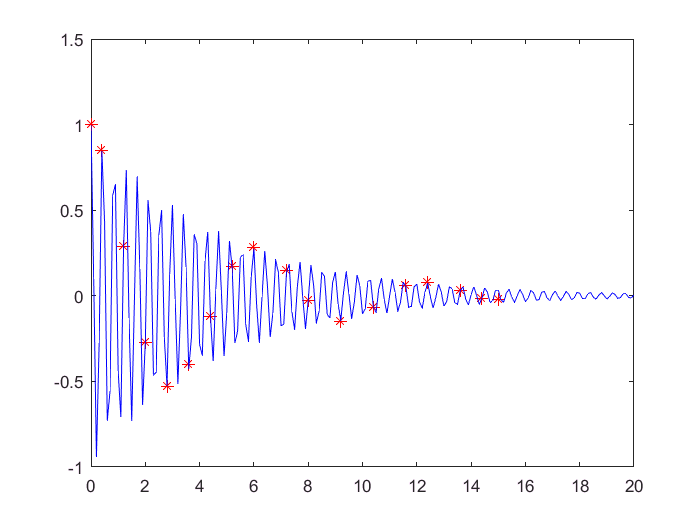

xi = 0:0.1:20;
yi = cfun(xi);
plot(x,y,'r*',xi,yi,'b-');